# Arctic Sea Ice 

**Learning Goals**

- Load and display Arctic sea ice extent GeoTIFF data.

- Quantify Arctic sea ice extent using logical operators.

- Use a for loop to analyze changes to Arctic sea ice from 1979 to 2021.

- Compute the linear trend of Arctic sea ice extent.

## Arctic Sea Ice Observations

Global temperature increase has been proposed as the cause of several deleterious climatological and weather effects. One such effect is the decline of Arctic sea ice. Sea ice decline has several ramifications, including sea level rise and decreased albedo in regions where ice used to exist. Decreased albedo can, in turn, cause more radiation to be absorbed, further warming the planet. This effect is known as ice-albedo feedback.

## 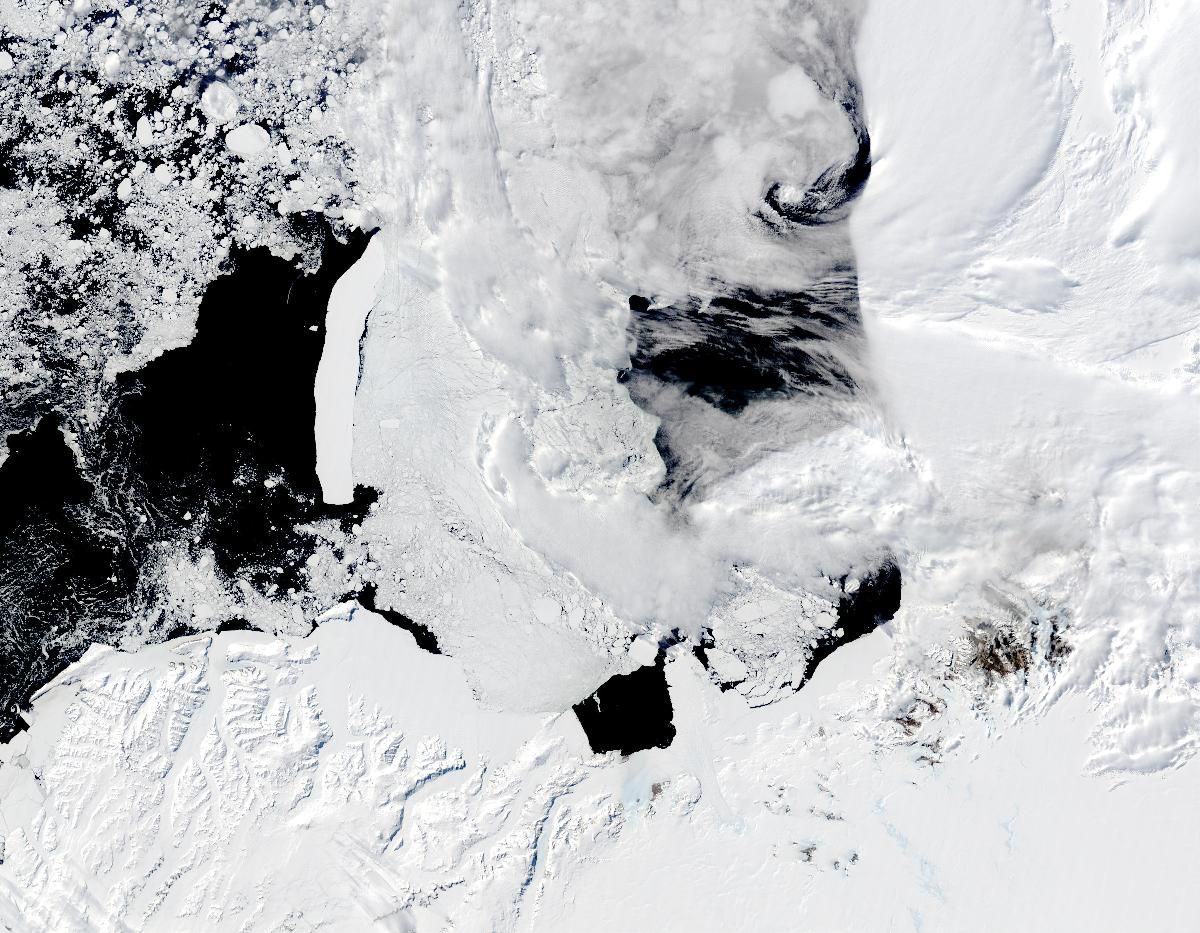

*Iceberg in the Ross Sea, Antarctica. Image courtesy of the NASA Visible Earth collection *[1]*.*

In this live script, you will explore Arctic sea ice data. The data is from the Sea Ice Index, Version 3, courtesy of the National Snow and Ice Data Center (NSIDC) [2]. This data is freely available from the NSIDC and can be downloaded [here](https://nsidc.org/data/G02135/versions/3).

   **Example. **Run this section to read and display the Arctic sea ice extent in September 2021. This example illustrates how you can read a data image and its colormap into MATLAB and display it.

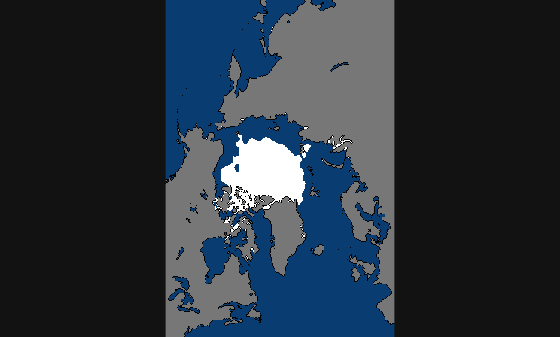

DataFile = "N_202109_extent_v3.0.tif";
[I,cmap] = imread(DataFile);
imshow(I,cmap)
title("Arctic sea ice extent in September 2021")

The extent of the Arctic sea ice is generally low in September due to melting during the summer. In other months, greater sea ice extent can be observed.

    **Activity. **In this activity, you will read and display the sea ice extent measured in different months and years.

**Task 1**. Read and display the Arctic sea ice extent data from February of 2021. The data files are named with the format:

`    N_YYYYMM_extent_v3.0.tif`

The YYYY and MM are replaced with the 4-digit year and 2-digit month.

**Hint: **Copy and modify the code from the previous example.

% Write your code here



**Task 2. **Comparing the extent of the Arctic sea ice between winter and summer months isn't especially relevant for analyzing climate change. Instead, you'll want to compare data from different years. Modify the code above to read the Arctic sea ice extent data from September 1981. How does it compare to the sea ice extent observed forty years later (but earlier in this script) in September 2021?

## Quantifying Extent

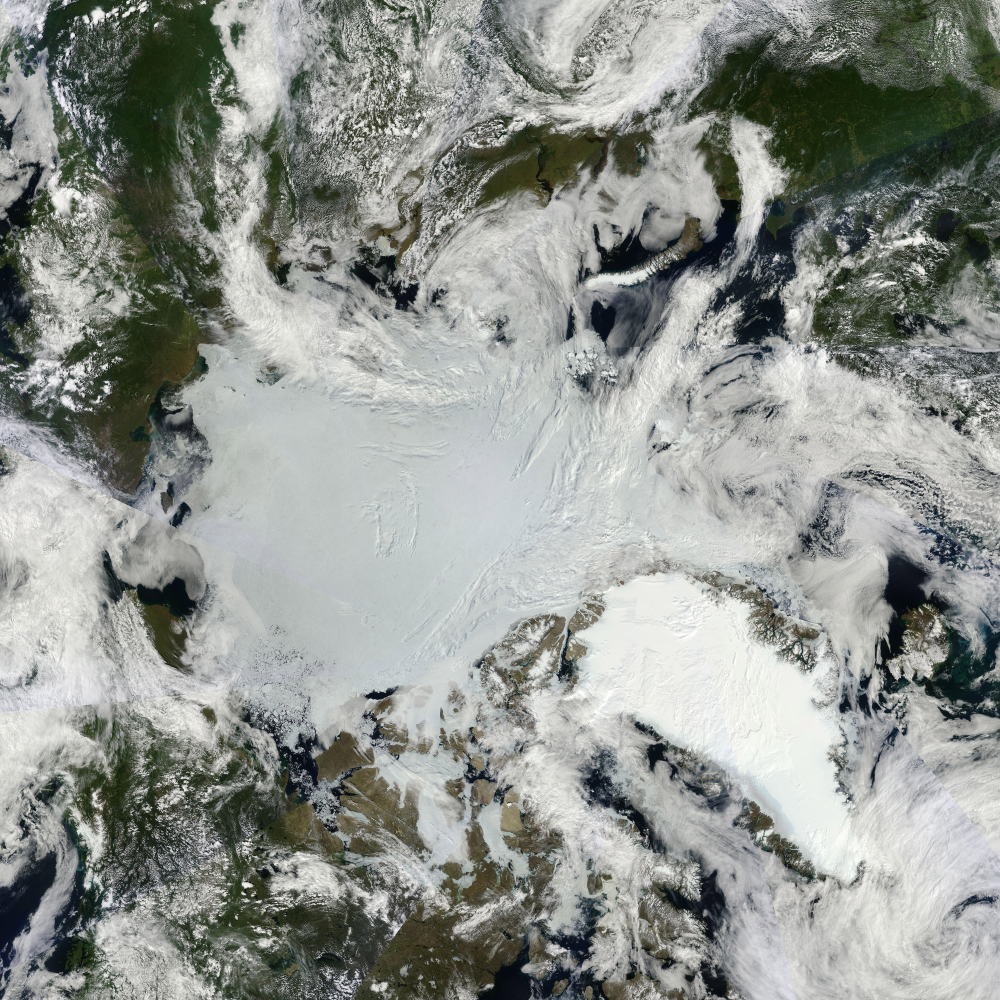

*Sunny skies over Arctic sea ice. True color image from the Moderate Resolution Imaging Spectroradiometer (MODIS) onboard NASA's Terra satellite. Acquired July 11, 2011. NASA image courtesy *[*MODIS Rapid Response Team*](http://rapidfire.sci.gsfc.nasa.gov/)* at NASA GSFC. *[3]

Clearly, there is more sea ice in the winter than at the end of summer. It also appears that there is more ice in 1981 than in 2021. But how much more? In other words: what is the extent of the Arctic sea ice at each point in time? To find out, you can count the number of sea ice pixels in each GeoTIFF image and then multiply them by the physical area represented by each pixel.

   **Activity. **In this activity, you will compute the extent of the Arctic sea ice in September 1981 from GeoTIFF data.

**Task 1. **Copy your code from the last example to read the image data for September 1981. Then, run this section to reload the data.

% Write your code here




**Task 2. **Although the data is displayed in color, it actually contains only an $n \times m$ matrix of values (rather than an $n \times m \times 3$ array, the size of a typical RGB color image). Verify this by computing the size of the image data `I` you created in **Task 1** using the [`size`](https://www.mathworks.com/help/matlab/ref/size.html) function.

**Task 3. **The image data classifies different regions using various pixel values. For example, the ocean pixels have a value of 0.

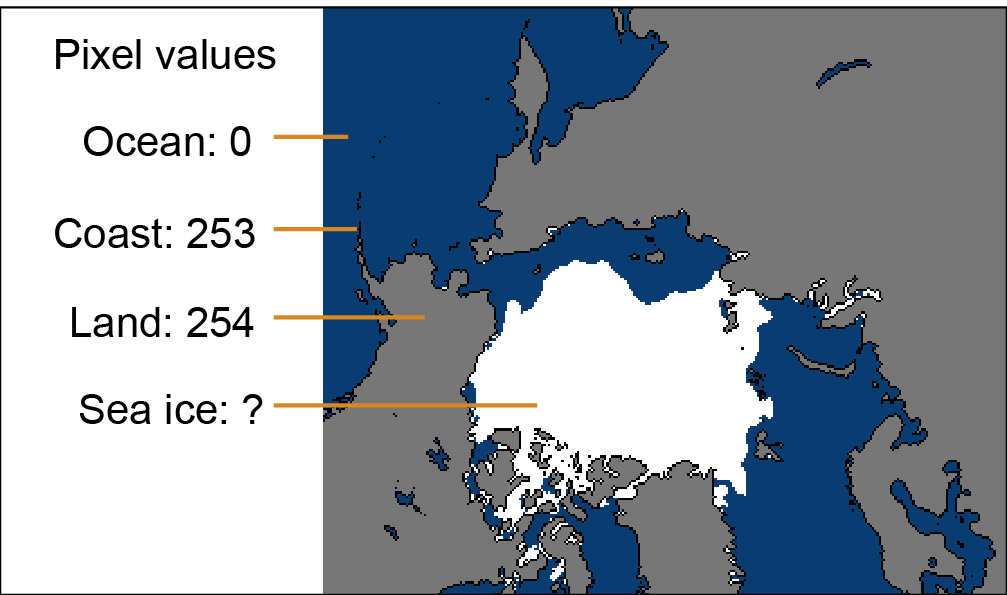

*Pixel values in the sea ice data *[3]*.*

What value represents sea ice? Store your answer below in `iceValue`.

**Hint:**

- Pop out the figure you created in **Task 1** by hovering over the image and then clicking .

- In the figure window, hover over the image and select the data tooltip  . Then, click on the ice. The **index **gives the value of the data array at the clicked location.

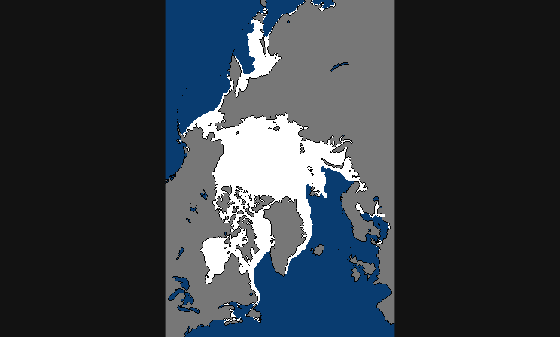

**Task 4. **Identify all the pixels that are ice and store the result in a variable named `ice`. To do so, compare the image data array `I` to `iceValue` using the logical [`==`](https://www.mathworks.com/help/matlab/ref/eq.html) operator. For example, to find all the ocean points, you would use

**Task 5. **The logical `==` operator returns a logical array that is 1 where the statement is true and 0 elsewhere. To identify the total number of pixels that contain ice, use the `nnz` function to count the number of non-zero values in the array `ice`. Store the result in `numIce`. 

**Task 6. **Each pixel of the map represents an area of 25 $\times$ 25 km (as mentioned in the metadata [here](https://nsidc.org/data/G02135/versions/3)). Compute the total area of sea ice in km$^2$ and store the result in `iceArea1981`.

 **Exercise. **In this exercise, you will compare the Arctic ice area in September 1981 to the extent present in September 2021.

**Question 1. **What is the total ice area measured in September 2021? Store your result in a variable named iceArea.

**Hint: **Follow similar steps to those used in the previous activity.

% Write your code here



**Question 2. **By what percentage did the ice area decrease between September 1981 and 2021? Store your result in a variable named `iceLoss`. The formula for percent loss is


$$\text{\% Loss}= \frac{\text{Initial value} - \text{Final value}}{|\text{Initial value}|} \cdot 100\%$$


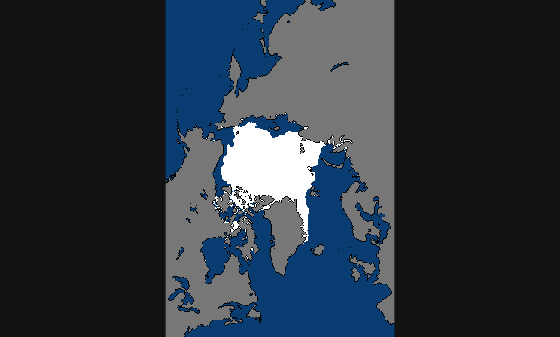

s =    448   304


numIce = 11136

iceArea1981 = 6960000

**References**

[1] Jacques Descloitres, MODIS Rapid Response Team, NASA/GSFC. Published January 3, 2003. C-19 iceberg in the Ross Sea, Antarctica. Accessed March 8, 2022 from [https://visibleearth.nasa.gov/images/63933/c-19-iceberg-in-the-ross-sea-antarctica](https://visibleearth.nasa.gov/images/63933/c-19-iceberg-in-the-ross-sea-antarctica).

[2] Fetterer, F., K. Knowles, W. N. Meier, M. Savoie, and A. K. Windnagel. 2017, updated daily. Sea Ice Index, Version 3. Northern sea ice extent subset. Boulder, Colorado USA. NSIDC: National Snow and Ice Data Center. doi: [https://doi.org/10.7265/N5K072F8](https://protect-us.mimecast.com/s/oz-ZC5yME6fnLED0IznV62?domain=doi.org). Accessed February 16, 2022.

[3] NASA image courtesy [MODIS Rapid Response Team](http://rapidfire.sci.gsfc.nasa.gov/) at NASA GSFC. Caption by Michon Scott. Accessed March 9, 2022 from [https://visibleearth.nasa.gov/images/51396/sunny-skies-over-arctic-sea-ice/51398l](https://visibleearth.nasa.gov/images/51396/sunny-skies-over-arctic-sea-ice/51398l).